%Live scripts para el analisis de los datos producidos
%DAPHNE V2A
clear all; 
close all;

%This section loads data to memory
%clear all
ch = 24; % channel number 
trigger_ch = 7;
template_ch = 0;
noise_ch = 0;
snr_dr_data_file_number = 3;
waveforms_length = 1024; %length of data
signal_file = "C:\Users\e_cri\OneDrive\Documents\INFN\DMEM\Mezzanine\Tests\V3_Mezz\Filter_PCB\FBK\33V5\vgain_scan\vgain_500\channel_24.7z";
template_file = "C:\Users\e_cri\Downloads\runs_cb_trigger\channel_23.7z";
noise_file = "C:\Users\e_cri\OneDrive\Documents\INFN\DMEM\DMEM_board\dmem_coldbox_coldtest_4\32V\noise_06038\channel_5.7z";
trigger_file = "C:\Users\e_cri\OneDrive\Documents\INFN\ColdBoxVD\DECEMBER2024_RUN\M4\run_34952\channel_7.7z";
roc_data_file = "C:\Users\e_cri\OneDrive\Documents\INFN\ColdBoxVD\DECEMBER2024_RUN\M4\roc_file_cb.mat";
snr_dr_data_file = "C:\Users\e_cri\Documents\NP04_vgain_scan\NP04_snr_dr_data.mat";
spe_model = "C:\Users\e_cri\OneDrive\Documents\INFN\ColdBoxVD\November2025_RUN\M3\Cold_Test\channel_24\cb_channel_24_signal_model.mat"

spe_model = "C:\Users\e_cri\OneDrive\Documents\INFN\ColdBoxVD\November2025_RUN\M3\Cold_Test\channel_24\cb_channel_24_signal_model.mat"

vgain = 500;
PDE = 45;
OV = 5;
Vbias = 30.5;
Threshold = 100;
Run = 34941;
self_trigger_file_number = 1;
% descomentar para otros analisis que no sean DAQ
% signal_file = split(signal_file,'run_');
% signal_file = signal_file(1);
% signal_file = strcat(signal_file,'run_',num2str(Run),'\channel_',num2str(ch),'.7z');
% 
% trigger_file = split(trigger_file,'run_');
% trigger_file = trigger_file(1);
% trigger_file = strcat(trigger_file,'run_',num2str(Run),'\channel_',num2str(trigger_ch),'.7z');

csv_data = false;
csv_noise = false;
csv_template = false;
pickle_daq_data = false;
osc_data = false;
osc_xml_file = "C:\Users\e_cri\OneDrive\Documents\INFN\DMEM\DMEM_board\saturation\data\run_III\board_1_ch2\board_1_ch2_vbias_31V5_cal1.bin";
osc_wfm_file = "C:\Users\e_cri\OneDrive\Documents\INFN\DMEM\DMEM_board\saturation\data\run_III\board_1_ch2\board_1_ch2_vbias_31V5_cal1.Wfm.bin";
pickle_file = "";
self_trigger_analysis = false;
use_derivative_trigger = false;

data_type = "uint16";

if(~csv_data && ~pickle_daq_data && ~osc_data)
    [data,mean_data,Tm] = extract_and_import_DAPHNE_data(ch,waveforms_length,signal_file,true,data_type,'l',false);
    [a,b] = size(data);
    data_trigger = zeros(a,b);
    if(self_trigger_analysis)
        [data_trigger,~,~] = extract_and_import_DAPHNE_data(trigger_ch,waveforms_length,trigger_file,true,data_type,'l',false);
    end
elseif(csv_data && ~pickle_daq_data)
    Tm = 16e-9;
    data = load(signal_file);
    mean_data = mean(data);
elseif(pickle_daq_data)
    Tm = 16e-9;
    [data, data_trigger, timestamps, channels, endpoints] = getDataFromWafflesPickleFile(ch,trigger_ch,pickle_file);
    mean_data = mean(data);
elseif(osc_data)
    waveform = readBinaryDataRSOsc(char(osc_xml_file),char(osc_wfm_file));
    data = waveform.waveforms;
    [a,b] = size(data);
    data_trigger = zeros(a,b);
    mean_data = waveform.mean_waveform;
    Tm = waveform.Resolution;
end

 
7-Zip 21.07 (x64) : Copyright (c) 1999-2021 Igor Pavlov : 2021-12-26 
 
Scanning the drive for archives: 
1 file, 46227731 bytes (45 MiB) 
 
Extracting archive: C:\Users\e_cri\OneDrive\Documents\INFN\DMEM\Mezzanine\Tests\V3_Mezz\Filter_PCB\FBK\33V5\vgain_scan\vgain_500\channel_24.7z 
-- 
Path = C:\Users\e_cri\OneDrive\Documents\INFN\DMEM\Mezzanine\Tests\V3_Mezz\Filter_PCB\FBK\33V5\vgain_scan\vgain_500\channel_24.7z 
Type = 7z 
Physical Size = 46227731 
Headers Size = 138 
Method = LZMA2:20 
Solid = - 
Blocks = 1 
 
Everything is Ok 
 
Size:       122880000 
Compressed: 46227731 


% % 7z file extraction 
% filename = strcat('channel_',num2str(ch));
% filedir = strcat('"',pwd,'\',filename,'.7z','"');
% extract_command = ['"C:\Program Files\7-Zip\7z.exe" e '  filedir];
% system(extract_command)
% 
% %importing data; false for txt file ; true for binary file
% [data,mean_data,Tm] = import_data_daphne_func(ch,waveforms_length,true,'l',true);
% clearvars -except ch data mean_data Tm;
% %filename_data = strcat('channel_',num2str(ch),'.mat');
% filename_data_raw = strcat('channel_',num2str(ch),'.dat');
% 
% % load data to memory and delete created files 
% %load(strcat('channel_',num2str(ch),'.mat'))
% %delete(filename_data)
% delete(filename_data_raw)

% Initial conditions values and settings

save_figures = false;
save_config = false;
use_config = false;
skip_hist_config = true; %uncheck when using the config file
invert_data = false;
use_rms_quantiles = true;
use_pedestal_quantiles = true;
use_quantiles_spe = true;
automatic_fit = true;
DAPHNE_int_on = false;
use_dr_peak2peak = true;
use_opt_filter = false;
use_opt_with_noise = false;
use_movmean = false;
normalize_histogram = true;
enable_hpf = true;
enable_movmean = true;
classic_integration = false;
special_filter = true;
enable_special_filter_notch = false;
enable_special_filter_hpf = false;

special_filter_type = "low";
special_filter_cutoff = 2;
special_filter_order = 3;
special_filter_cutoff_hpf = 40;
notch_bandstop = 2.05;
notch_Q = 15

notch_Q = 15


peaks_to_fit = 6;

enable_spe_estimation = false;


%% titles and names of files to be saved
title_str = "OV = %.1fV - VGAIN %d - SoF DCEM CH 17";
title_str = sprintf(title_str,OV,vgain);
id_string = "TESTSTAND - DAPHNE MEZZ";
save_histogram_string = "histogram";
save_histogram_string = strcat(save_histogram_string,'_ch_',num2str(ch));
save_singlePE_string ="average_single_PE";
save_singlePE_string = strcat(save_singlePE_string,'_ch_',num2str(ch));
save_avg_waveform_string ="average_PE";
save_avg_waveform_string = strcat(save_avg_waveform_string,'_ch_',num2str(ch));
save_trig_waveform_string ="average_trigger_signal";
save_trig_waveform_string = strcat(save_trig_waveform_string,'_ch_',num2str(ch));
save_dir = split(signal_file,strcat('channel_',num2str(ch),'.7z'));
save_dir = save_dir(1);
save_dir = strcat(save_dir,'figures\');
mkdir(save_dir);

%title_str = 'PDE = --%(V_{bias} = 32.5V) - C_{in} = 100{n}F - R_{b} = 0\Omega';
%title_str = '--% PDE - V_{bias} = 36V - C_{in} = 100nF - R_{b} = 0\Omega';
%title_str = 'Bypassed TRAFO - VGAIN 0.8V(~10dB total)';
%id_string = 'FBK DCEM AFE0 CH0'
% save_singlePE_string = 'average_single_PE'
% save_histogram_string = 'histogram'
% save_avg_waveform_string = 'average_PE'
save_config_string = 'analysis_config.mat'

save_config_string = 'analysis_config.mat'

integration_window = 1000;
pos_integral= 1;

int_low_limit = 127; % 353; 
circ_data =-100; %bicocca lab value: -300
load('C:/Users/e_cri/OneDrive/Documents/PhD/Investigacion/Electronica/DAPHNE test/daphne_configuration/Filters/fit_filter_vars.mat');
load('C:\Users\e_cri\OneDrive\Documents\PhD\Investigacion\Electronica\DAPHNE test\V2\HD_2024\HD_HPK\NOISE_CURVE\090\data.mat');
load(spe_model)
if(osc_data)
    Tm = waveform.Resolution;
end
if(use_opt_filter)
    %%% signal template
    if(~csv_template)
        %[signal_template,~,~] = extract_and_import_DAPHNE_data(ch,waveforms_length,template_file,true,data_type,'l',false);
        %mean_data_f = mean(signal_template);
        input_signal_opt = zeros(1,waveforms_length);
        input_signal_opt(250) = 1;
        mean_data_f = 10*filter(tf_model_d_k1.Numerator{1},tf_model_d_k1.Denominator{1},input_signal_opt);
    else
        signal_template = load(template_file);
        mean_data_f = -signal_template;
    end
    %%% noise template
    if(~csv_noise && use_opt_with_noise)
        [noise_data,~,~] = extract_and_import_DAPHNE_data(noise_ch,waveforms_length,noise_file,true,data_type,'l',false);
    elseif(csv_noise && use_opt_with_noise)
        noise_data = load(noise_file);
    else
        [a,~] = size(data);
        noise_data = rand(a,waveforms_length);
    end
    [~,col_noise_data] = size(noise_data); 
    mean_data_f = mean_data_f(1:col_noise_data);
    mean_data_f = (max(mean_data))*mean_data_f/max(mean_data_f);
    [h_filt] = optimal_filter_for_daphne_gpessina_function(mean_data_f,noise_data,false,1,invert_data,true,use_opt_with_noise,int_low_limit);
    num_opt = h_filt(end-200:end);
    den_opt = 1;
    noise_dir = split(signal_file,'channel');
    save(strcat(noise_dir(1),'opt_filt.mat'),'h_filt');
end
% load('C:/Users/e_cri/OneDrive/Documents/PhD/Investigacion/Electronica/DAPHNE test/V2/10022023/FBK/ch0/cal_30000/single_pe.mat','total_daphne_compensator','total_daphne_compensator_1u_2');
% load('C:/Users/e_cri/OneDrive/Documents/PhD/Investigacion/MATLAB/sim_cold_amp/transfer_function_estimation/optimun_filters_Rb0_cd_100n.mat')
% load('C:\Users\e_cri\OneDrive\Documents\PhD\Investigacion\Electronica\DAPHNE test\V2\10022023\FBK\ch0\cal_30000\single_pe_2.mat','eff_filter_f','hg_avg_f','hg_avg_recalc')
%load('optimun_filters_1p_comp.mat')
%load('../simulated_waveform.mat')
%load('filters.mat')
% [bh1,ah1] = butter(5,0.08e6/(62.5e6/2),'high');
% [bh2,ah2] = butter(5,1.2e6/(62.5e6/2),'high');
%  [zf,pf,kf] = besself(2,2*pi*0.08e6,'high');
%  [bh1,ah1] = zp2tf(zf,pf,kf);
%  [bh1,ah1]=bilinear(bh1,ah1,62.5e6);
%  [zf,pf,kf] = besself(1,2*pi*0.5e6,'high');
%  [bh2,ah2] = zp2tf(zf,pf,kf);
%  [bh2,ah2]=bilinear(bh2,ah2,62.5e6);
% [num_decimator,den_decimator] = butter(1,(62.5e6/(2*16))/(62.5e6/2),'low');
% [bl1,al1] = cheby1(2,0.5,1.2e6/(62.5e6/2),'low');
% [bh1,ah1] = cheby1(1,0.5,0.1e6/(62.5e6/2),'high');
% [bh2,ah2] = cheby1(1,0.5,0.800e6/(62.5e6/2),'high');
[b,a] = butter(3,0.14);
[num_bstop,den_bstop] = iirlp2bs(b,a,0.14,[0.0985 0.3]);
[sf1_b,sf1_a] = butter(special_filter_order,(special_filter_cutoff*1e6)/(62.5e6/2),special_filter_type);
if(enable_special_filter_notch)
    n_freq = (notch_bandstop*1e6)/(62.5e6/2);
    [sf1_b,sf1_a] = iirnotch(n_freq,n_freq/notch_Q);
end
if(enable_special_filter_hpf)
    [hpf1_b,hpf1_a] = butter(special_filter_order,(special_filter_cutoff_hpf*1e3)/(62.5e6/2),'high');
else
    hpf1_b = numz_planta_integrator;
    hpf1_a = denz_planta_integrator;
end
window_f = tukeywin(2048,1000/2048);

% Initial conditions values and settings
[total_data,len] = size(data);


decimation_factor = 1;
int_high_limit = int_low_limit+integration_window; 
trigger_sigma_sqrt_est = 13;
trigger_sigma_mult_high = 4;
trigger_sigma_mult_low = 3.8;
%trigger_high_window = 30;

filt_max_point = 382; % 382 ;

%     histogram_bin = 1e-9;
%     min_sep = 10;
% 
%     integral_window_1 = 2.7e-10;
%     integral_bin_number_1 = 11;
%     integral_window_2 = 2.7e-10;
%     integral_bin_number_2 = 12;
%     center_start = 1;

% Pedestal calculation 

rms_waveform_equal = zeros(1,total_data);
tiempo = 0:Tm:Tm*(len-1);
pedestal_25 = 0;
pedestal_75 = 0;
seed = 160; 
if(use_config)
    try
        load(save_config_string)
        disp('Using configuration file for seed and peak parameters.');
    catch
        seed = seed
        disp('No configuration file found.');
    end
end

rms_waveform_prev = 0;
rms_waveform_act = 0;
equal_value = 0;
for i=1:total_data
    rms_waveform_act = rms(data(i,:));
    if(rms_waveform_act == rms_waveform_prev)
        rms_waveform_equal(i) = true;
        equal_value = equal_value + 1;
    else
        rms_waveform_equal(i) = false;
    end
    rms_waveform_prev = rms_waveform_act;
end
equal_value

equal_value = 193

data = data(rms_waveform_equal == false,:);
if(self_trigger_analysis)
    data_trigger = data_trigger(rms_waveform_equal == false,:);
end
[total_data,len] = size(data);

rms_waveform = zeros(1,total_data);
% Remove data that has rms outlier
for i=1:total_data
    rms_waveform(i) = rms(data(i,:));
end

if(use_rms_quantiles)
    rms_quantiles = quantile(rms_waveform,[0.15 0.5 0.85]);
    rms_25 = rms_quantiles(1);
    rms_75 = rms_quantiles(3);
    data = data(rms_waveform >= rms_25,:);
    data_trigger = data_trigger(rms_waveform >= rms_25,:);
    rms_waveform = rms_waveform(rms_waveform >= rms_25);
    data = data(rms_waveform <= rms_75,:);
    data_trigger = data_trigger(rms_waveform <= rms_75,:);
    rms_waveform = rms_waveform(rms_waveform <= rms_75);
    [total_data,len] = size(data);
end

mean_trigger = zeros(1,len);
data_trigger_shifted = zeros(total_data,len);
pedestal = zeros(1,total_data);
for i=1:total_data
    data_ip = movmean(data(i,:),[integration_window 0]);
    pedestal(i) = calculateMedianPedestal(data_ip,int_low_limit,5,50,seed);
    %%%%% trigger signals %%%%%%
    if(self_trigger_analysis)
        trigger_data_i = data_trigger(i,:);
        if(use_derivative_trigger)
            trigger_sh = circshift(trigger_data_i,1);
            trigger_data_i = trigger_data_i - trigger_sh;
            trigger_data_i(1) = 0;
            trigger_data_i(trigger_data_i<0) = 0;
        end
        data_trigger_shifted(i,:) = trigger_data_i;
        mean_trigger = mean_trigger + trigger_data_i;
    end
    %%%%%%%%%%%%%%%%%%%%%%%%%%
end

if(self_trigger_analysis)
    mean_trigger = mean_trigger/total_data;
    [max_trigger_value,max_trigger_pos] = max(mean_trigger);
    [mu_trigger,sigma_trigger,gauss_fitted_trigger] = my_gaussian_fit(1:1:len,mean_trigger,max_trigger_value,max_trigger_pos,trigger_sigma_sqrt_est);
    gauss_fitted_trigger_data = gauss_fitted_trigger(1:1:len);
    [~,max_trigger_pos] = max(gauss_fitted_trigger_data);
    trigger_low_window = ceil(sigma_trigger*trigger_sigma_mult_low);
    trigger_high_window = ceil(sigma_trigger*trigger_sigma_mult_high);
end
%max_trigger_pos = 1449;

if(use_movmean)
    data_ip = movmean(mean_data,[integration_window 0]);
else
    %data_ip = wdenoise(mean_data - mean(mean_data(1:int_low_limit)),4);
    data_ip = filter(numz_planta_movmean_hpk,denz_planta_movmean_hpk,mean_data - mean(mean_data(1:int_low_limit)));
end

if(~invert_data)
    max_data_ip = data_ip - mean(data_ip(1:int_low_limit));
else
    max_data_ip = -data_ip + mean(data_ip(1:int_low_limit));
end
if(~DAPHNE_int_on)
    %max_data_ip = filter(afe_compensator_num ,afe_compensator_den,max_data_ip);
    max_data_ip = filter(numz_planta_integrator,denz_planta_integrator,max_data_ip);
end
if(special_filter)
    max_data_ip = filter(sf1_b,sf1_a,max_data_ip);
end
if(use_opt_filter)
    if(~invert_data)
        data_ip = mean_data - mean(mean_data(1:int_low_limit));
    else
        data_ip = -mean_data + mean(mean_data(1:int_low_limit));
    end
    opt_max_data_ip = filter(num_opt,den_opt,circshift(data_ip,circ_data));
    [filt_max_value,filt_max_point] = max(opt_max_data_ip); % Overrides line 83
else
    [filt_max_value,filt_max_point] = max(max_data_ip); % Overrides line 83
end

if(~normalize_histogram)
     filt_max_value = 1;
end
filter_int_low = filt_max_point - pos_integral;
filter_int_high = filt_max_point + pos_integral;

if(use_pedestal_quantiles)
    pedestal_quantiles = quantile(pedestal,[0.15 0.5 0.85]);
    pedestal_25 = pedestal_quantiles(1);
    pedestal_75 = pedestal_quantiles(3);
    data = data(pedestal >= pedestal_25,:);
    data_trigger_shifted = data_trigger_shifted(pedestal >= pedestal_25,:);
    pedestal = pedestal(pedestal >= pedestal_25);
    data = data(pedestal <= pedestal_75,:);
    data_trigger_shifted = data_trigger_shifted(pedestal <= pedestal_75,:);
    pedestal = pedestal(pedestal <= pedestal_75);
    [total_data,len] = size(data);
end

% amplitude_signal = zeros(1,total_data);
% for i=1:total_data
%     data_ip = data(i,:);
%     amplitude_signal(i) = abs(max(data_ip)-min(data_ip));
% end
% 
% data = data(amplitude_signal <= 500,:);
% [total_data,len] = size(data);

pedestal_value = mean(pedestal);

integral = zeros(1,total_data);
peak_jitter = zeros(1,total_data);
integral_triggered = zeros(1,total_data);
confusion_truth = zeros(1,total_data);
confusion_trigger = zeros(1,total_data);
mean_waveform = zeros(1,len);
mean_waveform2 = zeros(1,len/decimation_factor);
mean_deconv = zeros(1,len);
mean_fourier_i = zeros(1,len);
mean_fourier = zeros(1,floor(len/2) +1);
fourier_ = zeros(1,floor(len/2) + 1);
freq = zeros(1,len);
data_i = zeros(1,len);
data_2 = zeros(total_data,len/decimation_factor);
data_special_filter = zeros(1,len);

if(self_trigger_analysis)
    close all
    figure(1)
    plot(mean_trigger)
    xline(max_trigger_pos,'g--')
    xline(max_trigger_pos-trigger_low_window,'b--')
    xline(max_trigger_pos+trigger_high_window,'b--')
    grid on 
    hold on
    plot(gauss_fitted_trigger_data)
    xlim([max_trigger_pos-trigger_low_window-100 max_trigger_pos+trigger_high_window+100])
    title(strcat('Mean Trigger Signal -',{' '},id_string),'Interpreter','latex','FontSize',14)
    xlabel("CLK tics",'Interpreter','latex','FontSize',12)
    ylabel("A.U.",'Interpreter','latex','FontSize',12)
    legend("Average signal","Maximun Position","Trigger Acceptance Window",'Interpreter','latex','FontSize',10)
    if(save_figures)
        figure(1)
        if ~strcmp(get(gcf,'visible'),'on')
            invisible = true;
            set(gcf,"Visible","on");
        end
        saveas(gcf,strcat(save_dir,save_trig_waveform_string,'.fig'))
        saveas(gcf,strcat(save_dir,save_trig_waveform_string,'.png'))
    end
end

% if(~waitforbuttonpress)
%     disp('Ended execution')
%     return
% end


%ppm = ParforProgressbar(total_data);
for i=1:total_data
    if(invert_data)
        mean_waveform = mean_waveform + (-data(i,:) + pedestal(i));
        %mean_waveform = mean_waveform + (data(i,:));
        %mean_waveform = mean_waveform + filter(bl,al,-data(i,:) + pedestal_value);
    
        %%%%%%% ALL PASS %%%%%%%%%%%%%%%%%%%%
        data_i = -data(i,:) + pedestal(i);
        %data_i = (data(i,:) - pedestal_value);
        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        %%%%% SPECIAL FILTER %%%%%%%
        if(special_filter)
            data_special_filter = filter(sf1_b,sf1_a,data_i);
            data_i = data_special_filter;
        end
        %%%%%%%%%%%%%%%%%%%%%%%%%%%%
    else
        mean_waveform = mean_waveform + (data(i,:) - pedestal(i));
        %mean_waveform = mean_waveform + (data(i,:));
        %mean_waveform = mean_waveform + filter(bl,al,-data(i,:) + pedestal_value);
    
        %%%%%%% ALL PASS %%%%%%%%%%%%%%%%%%%%
        data_i = data(i,:) - pedestal(i);
        %data_i = (data(i,:) - pedestal_value);
        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

        %%%%% SPECIAL FILTER %%%%%%%
        if(special_filter)
            data_special_filter = filter(sf1_b,sf1_a,data_i);
            data_i = data_special_filter;
        end
        %%%%%%%%%%%%%%%%%%%%%%%%%%%%
    end

    %%%%% DECONVOLUTION %%%%%%%%%%%%%%%%%
    %deconv = weiner_deconv2(data_i,single_wfm,single_wfm,10e-12*mean_fourier_i);
    %mean_deconv = mean_deconv + deconv;
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

    %%%%%%% HIGH PASS FILTER %%%%%%%%%%%%
    data_2(i,:) = data_special_filter;
   %data_i = filter(total_daphne_compensator_1u_2.Numerator{1},total_daphne_compensator_1u_2.Denominator{1},data_i); % daphne undershoot compensator
   if(use_opt_filter)
       data_i = filter(num_opt,den_opt,circshift(data_i,circ_data));
   else
       if(~DAPHNE_int_on && enable_hpf)
           %data_i = filter(afe_compensator_num ,afe_compensator_den,data_i);
           data_i = filter(hpf1_b,hpf1_a,data_i);
       end
       %data_i_d = data_i;
       %data_i = filter(numz_planta_movmean_hpk,denz_planta_movmean_hpk,(data_i));
       %data_i_d = filter(Hwiener.Numerator{1},Hwiener.Denominator{1},(data_i));
       %data_i = filter(bh1,ah1,(data_i));
       if(use_movmean && enable_movmean)
           data_i = movmean(data_i,[integration_window 0]);
       elseif(enable_movmean)
           %data_i = wdenoise(data_i,4);
           data_i = filter(numz_planta_movmean_hpk,denz_planta_movmean_hpk,data_i);
       end
       %data_i = filter(num_bstop,den_bstop,data_i);
       %data_i = bandstop(data_i,[3.2e6 6.5e6],62.5e6);
   end
   data_i = data_i/filt_max_value;
    data_i_d = data_i;
    [~, peak_jitter(i)] = max(data_i_d(1:filt_max_point+20));
    peak_jitter(i) = peak_jitter(i);
    %data_i = circshift(data_i,-25);
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

    %%%%%%%%PEDESTAL RECOV HPF %%%%%%%%%%
%     data_i_lpf = filter(bl,al,(-data(i,:) + pedestal_value)); % IIR filter
%     data_i = filter(bh,ah,(-data(i,:) + data_i_lpf)); % IIR filter
%     data_i = data_i_lpf;
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%     %%%%%%%%%%%%% Matched filter freq %%%%%
%    Dominio de la frecuencia
%     data_i_fft = fft(data_i);
%     single_pe_fft = conj(fft(single_pe_ref3));
%     data_i = circshift(ifft(data_i_fft.*single_pe_fft),482);
%    Dominio Temporal decimator
     %coeff = hg_avg_recalc*0.1;
%      coeff = filter(num_decimator,den_decimator,single_pe_ref);
     % coeff = downsample(coeff(385:end),decimation_factor);
     % coeff = coeff(1:16)/max(coeff(1:16));
     % coeff2 = flip(coeff.*tukeywin(16,0.2)');
    %data_i_d = filter(coeff,1,downsample(data_i,decimation_factor));
    %data_i_d = circshift(conv(coeff,data_i),-4096);
    %data_i_d = data_i_d(1:2048);
%      data_i_d = filter(coeff2,1,downsample(filter(num_decimator,den_decimator,data_i),decimation_factor));
%      data_i_d = data_i; 
%      data_i_d = movmean(data_i_d,[2 0]);
    %%%%%%%%%%%%%%
%     Dominio Temporal completo
%      data_i = filter(flip(circshift(single_pe_ref,2046)),1,data_i);
%      data_i = 12*data_i/3000; 

    %%%%%%%%%%%%% Matched filter time %%%%%%
    % data_i = filter(flip(downsample(single_pe_ref(350:350+(8*32)-1),32)),[1],data_i)
    % data_i = data_i;
    %%%%%%%%%%%%%%

        %%%%%%%%%%%%% wiener filter time %%%%%%
    % data_i = circshift(detrend(data_i),115)
    % data_i = filter(num_decimator,den_decimator,data_i);
    % data_i_d = downsample(data_i,16);
    % data_i_d = filter(optimun_filter_decimated_16(1:end),1,data_i_d);
    % data_i_d = data_i_d;

    %%%%%%% fractional fourier filtering %%%%%%%%%%%%%%
     % data_i_d = [real(F_a_i*data_i(1:end-1)')' 0];

    %data_i = (-data(i,:) + mean(data(i,270)));
    %data_2(i,:) = data_i_d;
    mean_waveform2 = mean_waveform2 + data_i_d;
    [~, fourier_] = f_fourier(data_i,Tm,false,"dBFS");
    mean_fourier_i = mean_fourier_i + abs(fft(data_i)).^2;
    mean_fourier = fourier_ + mean_fourier; 
    %% integral values 
    %integral(i) = trapz(tiempo(int_low_limit:int_high_limit),data_i(int_low_limit:int_high_limit));
    if(classic_integration)
        integral(i) = trapz(data_i_d(int_low_limit:int_high_limit));
    else
        integral(i) = mean(data_i_d(filter_int_low:filter_int_high))*2;
    end
    %plot(data(i,:))
    %pause(0.1)
    %ppm.increment();
end
integral = integral(integral ~= 0); 
debug_val_min = -0.6

debug_val_min = -0.6000

debug_val_max = 0.5

debug_val_max = 0.5000

if(self_trigger_analysis)
    k = 1;
    for i=1:total_data
        data_trigger_i = data_trigger_shifted(i,:);
        % trigger_sh = circshift(data_trigger_i,1);
        % data_trigger_i = data_trigger_i - trigger_sh;
        % data_trigger_i(1) = 0;
        % data_trigger_i(data_trigger_i<0) = 0;
        if(sum(data_trigger_i((max_trigger_pos-trigger_low_window):(max_trigger_pos+trigger_high_window)))>0)
            integral_triggered(k) = integral(i);
            k=k+1;
            if(debug_val_max>integral(i) && debug_val_min<integral(i))
                debug_aux = 5;
            end
        else
            if(debug_val_max>integral(i) && debug_val_min<integral(i))
                debug_aux = 5;
            end
        end
    end
    integral_triggered = integral_triggered(1:k-1);
    virtual_trigger_pos = -10:0.1:60;
    true_positives_vector = zeros(1,length(virtual_trigger_pos));
    true_negatives_vector = zeros(1,length(virtual_trigger_pos));
    cond_present_vector = zeros(1,length(virtual_trigger_pos));
    cond_absent_vector = zeros(1,length(virtual_trigger_pos));
    all_sampled_vector = zeros(1,length(virtual_trigger_pos));
    
    for vtp=1:length(virtual_trigger_pos)
        % confusion_truth = 0;
        % confusion_trigger = 0;
        % true_positives = 0;
        % true_negatives = 0;
        % false_positives = 0;
        % false_negatives = 0;
        virtual_trigger_pos_vtp = virtual_trigger_pos(vtp);
        %% alternative method
        true_positives = length(integral_triggered(integral_triggered>=virtual_trigger_pos_vtp));
        false_negatives = length(integral(integral>=virtual_trigger_pos_vtp)) - true_positives;
        false_positives = length(integral_triggered(integral_triggered<virtual_trigger_pos_vtp));
        true_negatives = length(integral(integral<virtual_trigger_pos_vtp)) - false_positives;
        %%
        %for i=1:total_data
            % confusion_truth = 0;
            % confusion_trigger = 0;
            % integral_i = integral(i);
            % data_trigger_i = data_trigger_shifted(i,:);
            % % trigger_sh = circshift(data_trigger_i,1);
            % % data_trigger_i = data_trigger_i - trigger_sh;
            % % data_trigger_i(1) = 0;
            % % data_trigger_i(data_trigger_i<0) = 0;
            % if(integral_i >= virtual_trigger_pos_vtp)
            %     confusion_truth = 1;
            % end
            % if(sum(data_trigger_i((max_trigger_pos-trigger_low_window):(max_trigger_pos+trigger_high_window)))>0)
            %     confusion_trigger = 1;
            % end
            % if(confusion_truth && confusion_trigger)
            %     true_positives = true_positives + 1;
            % elseif(confusion_truth && ~confusion_trigger)
            %     false_negatives = false_negatives + 1;
            % elseif(~confusion_truth && confusion_trigger)
            %     false_positives = false_positives + 1;
            % else
            %     true_negatives = true_negatives + 1;
            % end

            
        %end

        cond_present = true_positives + false_negatives;
        cond_absent = false_positives + true_negatives;
        positives = true_positives + false_positives;
        negatives = false_negatives + true_negatives;
        all_sampled = true_positives + false_positives + false_negatives + true_negatives;
        
        assert(all_sampled == total_data);
        assert(all_sampled == cond_present + cond_absent);
        assert(all_sampled == positives + negatives);

        true_positives_vector(vtp) = true_positives;
        true_negatives_vector(vtp) = true_negatives;
        cond_present_vector(vtp) = cond_present;
        cond_absent_vector(vtp) = cond_absent;
        all_sampled_vector(vtp) = all_sampled;

        % confusion_truth = 0;
        % confusion_trigger = 0;
        % true_positives = 0;
        % true_negatives = 0;
        % false_positives = 0;
        % false_negatives = 0;
        %k_true = false;
    end

    if isfile(roc_data_file)
        load(roc_data_file)
    end
    
    for vtp=1:length(virtual_trigger_pos)
        
        roc_data{self_trigger_file_number}.trigger_file = trigger_file;
        roc_data{self_trigger_file_number}.estimated_trigger_pos = 0;
        roc_data{self_trigger_file_number}.estimated_pos_accuracy = 0;
        roc_data{self_trigger_file_number}.estimated_pos_tpr = 0;
        roc_data{self_trigger_file_number}.estimated_pos_fpr = 0;
        roc_data{self_trigger_file_number}.delta_pe = 0;
        roc_data{self_trigger_file_number}.data{vtp}.virtual_trigger_pos = virtual_trigger_pos(vtp);
        roc_data{self_trigger_file_number}.data{vtp}.sensitivity = true_positives_vector(vtp)/cond_present_vector(vtp);
        roc_data{self_trigger_file_number}.data{vtp}.specificity = true_negatives_vector(vtp)/cond_absent_vector(vtp);
        roc_data{self_trigger_file_number}.data{vtp}.accuracy = (true_positives_vector(vtp) + true_negatives_vector(vtp))/all_sampled_vector(vtp);
        %save(roc_data_file,"roc_data");
    end

    [estimated_threshold_position, pos_accuracy, pos_tpr, pos_fpr] = ROC_file_analysis(roc_data,self_trigger_file_number,false);
    roc_data{self_trigger_file_number}.estimated_trigger_pos = estimated_threshold_position;
    roc_data{self_trigger_file_number}.estimated_pos_accuracy = pos_accuracy;
    roc_data{self_trigger_file_number}.estimated_pos_tpr = pos_tpr;
    roc_data{self_trigger_file_number}.estimated_pos_fpr = pos_fpr;
    roc_data{self_trigger_file_number}.trigger_low_window = trigger_low_window;
    roc_data{self_trigger_file_number}.trigger_high_window = trigger_high_window;

    tpr = zeros(1,length(roc_data{self_trigger_file_number}.data));
    fpr = zeros(1,length(roc_data{self_trigger_file_number}.data));
    for i=1:length(roc_data{self_trigger_file_number}.data)
        tpr(i) = roc_data{self_trigger_file_number}.data{i}.sensitivity;
        fpr(i) = 1 - roc_data{self_trigger_file_number}.data{i}.specificity;
    end
    roc_data{self_trigger_file_number}.pauc = trapz(fpr,tpr);
    M_pauc = fpr(end) - fpr(1);
    m_pauc = 0.5*(fpr(end) - fpr(1))*(fpr(end) + fpr(1));
    roc_data{self_trigger_file_number}.pauc_n = 0.5*( 1 + (roc_data{self_trigger_file_number}.pauc - m_pauc)/(M_pauc-m_pauc) );
    roc_data{self_trigger_file_number}.gini = (roc_data{self_trigger_file_number}.pauc_n - 0.5)/0.5;
    save(roc_data_file,"roc_data");
end


[freq, ~] = f_fourier(data(1,:),Tm,false,"dBFS");
mean_waveform = (mean_waveform/total_data);
ts = timeseries(mean_waveform,tiempo);
mean_waveform2 = (mean_waveform2/total_data);
mean_fourier = mean_fourier/total_data;
mean_fourier_i = mean_fourier_i/total_data;
mean_deconv = mean_deconv/total_data;

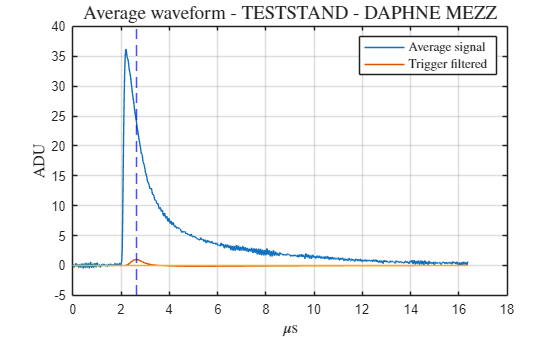

close all
figure(2)

plot(downsample(tiempo,decimation_factor)*1e6,downsample(mean_waveform,decimation_factor))
hold on 
plot(downsample(tiempo,decimation_factor)*1e6,mean_waveform2)
plot(tiempo*1e6,mean_deconv)
%xline(tiempo(int_low_limit)*1e6,'r--')
%xline(tiempo(int_high_limit)*1e6,'r--')
xline(tiempo(filt_max_point)*1e6,'b--')
grid on 
title(strcat('Average waveform -',{' '},id_string),'Interpreter','latex','FontSize',14)
xlabel("$\mu$s",'Interpreter','latex','FontSize',12)
ylabel("ADU",'Interpreter','latex','FontSize',12)
legend("Average signal","Trigger filtered",'Interpreter','latex','FontSize',10)


if(save_figures)
    figure(2)
    if ~strcmp(get(gcf,'visible'),'on')
        invisible = true;
        set(gcf,"Visible","on");
    end
    saveas(gcf,strcat(save_dir,save_avg_waveform_string,'.fig'))
    saveas(gcf,strcat(save_dir,save_avg_waveform_string,'.png'))
end

%close(fig1)


min_localmax_peak_pos = -0.5000

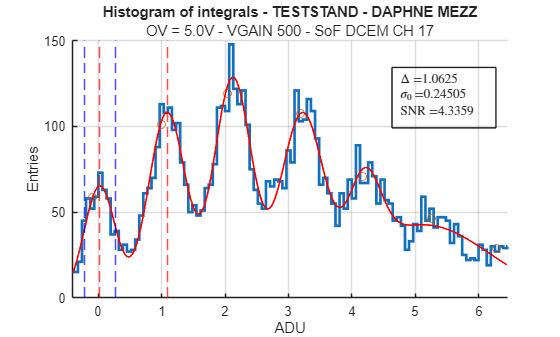

if(~automatic_fit) %%%% MANUAL FIT %%%%

% histogram_bin =1.95
% min_sep = 9
% 
% integral_window_1 = 6.25
% integral_bin_number_1 = 16
% integral_window_2 = 4.5
% integral_bin_number_2 = 15
% center_min = -5
% center_max = 15
% 
% x_axis_low_limit = -14
% x_axis_high_limit = 46
% 
% center_hist_1_plus = 1.21
% center_hist_1_neg = 1
% center_hist_2_plus = 1.18
% center_hist_2_neg = 0.88

if(use_config && ~skip_hist_config)
    try
        load(save_config_string)
        disp('Using configuration file for fit parameters.');
    catch
        disp('No configuration file found.');
    end
end
%close all
figure(2)
hold on
h = histogram(integral,'BinWidth',histogram_bin,'DisplayStyle','stairs');
set(h,'lineWidth',2);
grid on 


V = h.Values;
E = h.BinEdges;
% Use islocalmax
L = islocalmax(V,'MinSeparation',min_sep);

% Find the centers of the bins that islocalmax identified as peaks
left = E(L);
right = E([false L]);
center = (left + right)/2;

plot(center, V(L), 'o')

[~,center_start] = max(center>center_min & center<center_max);

selected_values_fit = integral((integral < center(center_start) + center_hist_1_plus*integral_window_1));
selected_values_fit = selected_values_fit((selected_values_fit > center(center_start) - center_hist_1_neg*integral_window_1));
hf = histfit(selected_values_fit,integral_bin_number_1,'normal');
set(hf(2),'lineWidth',1.3,'LineStyle','-');
delete(hf(1));
h1_fit1 = hf(2);
[mu1,sigma1] = normfit(selected_values_fit);


selected_values_fit = integral((integral < center(center_start + 1) + center_hist_2_plus*integral_window_2));
selected_values_fit = selected_values_fit((selected_values_fit > center(center_start + 1) - center_hist_2_neg*integral_window_2));
hf = histfit(selected_values_fit,integral_bin_number_2,'normal');
set(hf(2),'lineWidth',1.3,'LineStyle','-');
delete(hf(1));
h1_fit2 = hf(2); 
[mu2,sigma2] = normfit(selected_values_fit);

[x_data_fit,y_data_fit] = sum_fitted_data(h1_fit1,h1_fit2,mu1,sigma1,mu2,sigma2);
plot(h1_fit1.XData,h1_fit1.YData,'r-.','LineWidth',1)
plot(h1_fit2.XData,h1_fit2.YData,'r-.','LineWidth',1)
plot(x_data_fit,y_data_fit,'r','LineWidth',1.5)
delete(h1_fit1);
delete(h1_fit2);

xline(mu1,'r--')
delta = mu2 - mu1;
SNR = delta/sigma1;
SNR1 = delta/sqrt(sigma1*sigma1 + sigma2*sigma2)

% str = strcat('$\Delta$ = ', num2str(delta),sprintf("\n"),'$\sigma_{0}$ = ', num2str(sigma1),sprintf("\n"), '$SNR_{0}$ = ' ...
%     ,num2str(SNR),sprintf("\n"),'$SNR_{1}$ = ',num2str(SNR1));
str = strcat('$\Delta$ = ', num2str(delta),sprintf("\n"),'$\sigma_{0}$ = ', num2str(sigma1),sprintf("\n"), 'SNR = ' ...
   ,num2str(SNR));
annotation('textbox' ,[0.6, 0.5, 0.1, 0.1],'interpreter','latex', 'String', str)

title(strcat('Histogram of integrals -',{' '}, id_string), title_str)
ylabel('Entries')
xlabel('ADU')
xlim([x_axis_low_limit x_axis_high_limit])
xline(mu1 + sigma1,'b--')
xline(mu1 - sigma1,'b--')
xline(mu2,'r--')

else %%%% AUTOMATIC FIT %%%%

% number_of_bins = 200;    
% x_axis_low_limit = min(integral);
% x_axis_high_limit = max(integral);   
% histogram_bin = (x_axis_high_limit - x_axis_low_limit)/number_of_bins;

histogram_bin_init =0.02;
histogram_bin_end =0.05;
histogram_bin_step =0.01;

min_sep = 0.8;
min_localmax_peak_pos = -0.5

x_axis_low_limit = -0.25;
x_axis_high_limit = 4;

center_min = -0.5;
center_max = 0.5;

init_sigma_2_sqrt = 0.3;
 

if(use_config && ~skip_hist_config)
    try
        load(save_config_string)
        disp('Using configuration file for fit parameters.');
    catch
        disp('No configuration file found.');
    end
end


close all
figure(2)
hold on

histogram_bin_vec = histogram_bin_init:histogram_bin_step:histogram_bin_end;
SNR_vec = zeros(1,length(histogram_bin_vec));
peak_position = [];
peak_positions = {};
k = 1;
for i=1:length(histogram_bin_vec)
    [mu1,sigma1,mu2,sigma2,delta,SNR_vec(i),x_hist_plot,gauss_fitted_curve,~,peak_position] = gaussian_fit_SNR(integral,histogram_bin_vec(i),min_sep,min_localmax_peak_pos,x_axis_low_limit,x_axis_high_limit,center_min,center_max,init_sigma_2_sqrt,peaks_to_fit,45);
    peak_positions{k} = peak_position;
    k = k + 1;
end

close all
figure(2)
hold on
%SNR_vec = SNR_vec(SNR_vec < 2*mode(SNR_vec));
[~,max_snr_pos] = max(SNR_vec);
peak_position = peak_positions{max_snr_pos};
integral = integral./peak_position(2);
histogram_bin_vec(max_snr_pos) = histogram_bin_vec(max_snr_pos)/peak_position(2);
min_sep = min_sep/peak_position(2);
x_axis_low_limit = x_axis_low_limit/peak_position(2);
x_axis_high_limit = x_axis_high_limit/peak_position(2);
[mu1,sigma1,mu2,sigma2,delta,SNR,x_hist_plot,gauss_fitted_curve,~, ~] = gaussian_fit_SNR(integral,histogram_bin_vec(max_snr_pos),min_sep,min_localmax_peak_pos,x_axis_low_limit,x_axis_high_limit,center_min,center_max,init_sigma_2_sqrt, peaks_to_fit, 45);

if(self_trigger_analysis)
    h_triggered = histogram(integral_triggered,'BinWidth',histogram_bin_vec(max_snr_pos),'DisplayStyle','stairs');
    set(h_triggered,'lineWidth',2);
end
%%%%

plot(x_hist_plot,gauss_fitted_curve','r','LineWidth',1.25)
xline(mu1,'r--')
xline(mu1 + sigma1,'b--')
xline(mu1 - sigma1,'b--')
xline(mu2,'r--')
if(self_trigger_analysis)
    xline(roc_data{self_trigger_file_number}.estimated_trigger_pos,'g--','LineWidth',1)
end

str = strcat('$\Delta$ = ', num2str(delta),sprintf("\n"),'$\sigma_{0}$ = ', num2str(sigma1),sprintf("\n"), 'SNR = ' ...
   ,num2str(SNR));
annotation('textbox' ,[0.7, 0.7, 0.1, 0.1],'interpreter','latex', 'String', str)

title(strcat('Histogram of integrals -',{' '}, id_string), title_str)
ylabel('Entries')
xlabel('ADU')

if(self_trigger_analysis)
    if isfile(roc_data_file)
        load(roc_data_file)
    end
    roc_data{self_trigger_file_number}.delta_pe = delta;
    save(roc_data_file,"roc_data");
end

end


if(save_figures)
    figure(2)
    if ~strcmp(get(gcf,'visible'),'on')
        invisible = true;
        set(gcf,"Visible","on");
    end
    saveas(gcf,strcat(save_dir,save_histogram_string,'.fig'))
    saveas(gcf,strcat(save_dir,save_histogram_string,'.png'))
end

% sigma1
% sigma2
%close(fig2)

condition_waveform = zeros(1,len);
[number_of_waveforms,~] = size(data);  
condition_waveform_matrix = zeros(number_of_waveforms,len);
condition_cnt = 0;
for i=1:total_data
    if(invert_data)
        data_i = (-data(i,:) + pedestal(i));
    else
        data_i = (data(i,:) - pedestal(i));
    end
    if(special_filter)
        data_i = data_2(i,:);
    end
    %data_i_2 = filter(numz_planta_tf_movmean40,denz_planta_tf_movmean40,(-data(i,:) + pedestal_value)); % IIR filter
    if(integral(i) > mu2 - 2*sigma2 && integral(i) < mu2 + 2*sigma2)
        condition_waveform = condition_waveform + data_i;
        condition_cnt = condition_cnt + 1;
        condition_waveform_matrix(condition_cnt,:) = data_i;
    end
    %plot(data(i,:))
    %pause(0.1)
end
condition_waveform = condition_waveform/condition_cnt;
condition_waveform_matrix = condition_waveform_matrix(1:condition_cnt,:);



if(use_quantiles_spe)
    pedestal_single = zeros(1,condition_cnt);
    for i=1:condition_cnt
        data_ip = movmean(condition_waveform_matrix(i,:),[integration_window 0]);
        pedestal_single(i) = calculateMedianPedestal(data_ip,int_low_limit,15,20,seed);
    end


    pedestal_quantiles = quantile(pedestal_single,[0.15 0.5 0.85]);
    pedestal_25 = pedestal_quantiles(1);
    pedestal_75 = pedestal_quantiles(3);
    condition_waveform_matrix = condition_waveform_matrix(pedestal_single >= pedestal_25,:);
    pedestal_single = pedestal_single(pedestal_single >= pedestal_25);
    condition_waveform_matrix = condition_waveform_matrix(pedestal_single <= pedestal_75,:);
    pedestal_single = pedestal_single(pedestal_single <= pedestal_75);
    [condition_cnt,~] = size(condition_waveform_matrix);
end
condition_waveform = mean(condition_waveform_matrix);

if(enable_spe_estimation)
    fitted_spe_signal = fit2SPE(tf_model_d_k1,condition_waveform);
end


close all
figure(3)
semilogx(freq*1e-6,20*log10((mean_fourier)/2^14)) 

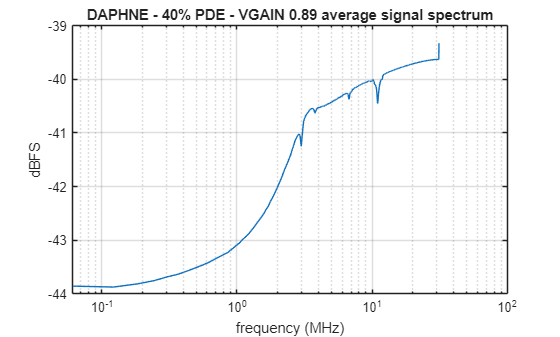

%semilogx(freq*1e-6,mean_fourier) 
hold on
grid on
%semilogx(freq*1e-6,20*log10((0.21*ones(1,1024/2 +1))/2^14))

title('DAPHNE - 40% PDE - VGAIN 0.89 average signal spectrum')
xlabel('frequency (MHz)')
ylabel('dBFS')

%close(fig3)

close all
figure(4)
plot((tiempo*1e6),condition_waveform);
hold on 
grid on 
mean_spe = condition_waveform;
if(enable_spe_estimation)
    figure(4)
    plot((tiempo*1e6),fitted_spe_signal);
    condition_waveform = fitted_spe_signal;
end
title(strcat('Average single PE -',{' '},id_string),title_str)
[~,max_mean_waveform] = max(mean_waveform);
yline(max(condition_waveform(max_mean_waveform-50:max_mean_waveform+200)),'r--')
yline(min(condition_waveform(max_mean_waveform-50:max_mean_waveform+200)),'r--')
% xline(tiempo(int_low_limit)*1e6,'b--')
% xline(tiempo(int_high_limit)*1e6,'b--')
dynamic_range = 0;
if(use_dr_peak2peak)
    str = strcat('Amplitude = ', num2str(max(condition_waveform(max_mean_waveform-100:max_mean_waveform+200)) - min(condition_waveform(max_mean_waveform-100:max_mean_waveform+200))))
    annotation('textbox', [0.5, 0.7, 0.1, 0.1], 'String', str)
    str = strcat('Dynamic range = ', num2str(2^14/(max(condition_waveform(max_mean_waveform-100:max_mean_waveform+200)) - min(condition_waveform(max_mean_waveform-100:max_mean_waveform+200)))))
    dynamic_range = num2str(2^14/(max(condition_waveform(max_mean_waveform-100:max_mean_waveform+200)) - min(condition_waveform(max_mean_waveform-100:max_mean_waveform+200))));
else
    str = strcat('Peak = ', num2str(max(condition_waveform(max_mean_waveform-100:max_mean_waveform+100))))
    annotation('textbox', [0.5, 0.7, 0.1, 0.1], 'String', str)
    %str = strcat('Dynamic range = ', num2str(((2^14)/2)/(max(condition_waveform))))
    str = strcat('Dynamic range = ', num2str(((2^14))/(max(condition_waveform(max_mean_waveform-100:max_mean_waveform+100)))))
    dynamic_range = num2str(((2^14))/(max(condition_waveform(max_mean_waveform-100:max_mean_waveform+100))))
end

str = 'Amplitude =12.3274'

str = 'Dynamic range =1329.075'

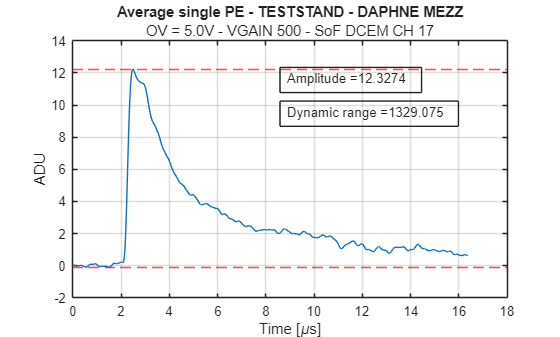


annotation('textbox', [0.5, 0.6, 0.1, 0.1], 'String', str)
xlabel('Time [\mus]')
ylabel('ADU')

if(save_figures)
    figure(4)
    if ~strcmp(get(gcf,'visible'),'on')
        invisible = true;
        set(gcf,"Visible","on");
    end
    saveas(gcf,strcat(save_dir,save_singlePE_string,'.fig'))
    saveas(gcf,strcat(save_dir,save_singlePE_string,'.png'))
end
%legend(strcat('channel ',num2str(ch-1)))
%close(fig4)

if(save_config && ~automatic_fit)
        save(save_config_string,'int_low_limit','filt_max_point','histogram_bin', ...
            'min_sep','integral_window_1','integral_bin_number_1','integral_window_2','integral_bin_number_2', ...
            'center_start','x_axis_low_limit','x_axis_high_limit','center_hist_1_plus', ...
            'center_hist_1_neg','center_hist_2_plus','center_hist_2_neg','seed');
elseif(save_config && automatic_fit)
    save(save_config_string,'int_low_limit','filt_max_point','histogram_bin', ...
            'x_axis_low_limit','x_axis_high_limit', ...
            'seed');
end

if isfile(snr_dr_data_file)
    load(snr_dr_data_file)
end

snr_dr_data{snr_dr_data_file_number}.vgain = vgain;
snr_dr_data{snr_dr_data_file_number}.snr = SNR;
snr_dr_data{snr_dr_data_file_number}.dynamic_range = dynamic_range;
snr_dr_data{snr_dr_data_file_number}.vbias = Vbias;
%save(snr_dr_data_file,"snr_dr_data");
